% Jacob Dunn 333 Final Project
% Documentation Statement: C2C Carrig and C2C Heath and I consulted on
% solutions when issues arose. Also, refernced the code provided on the
% board provided by Dr. Dudevoir.

% Approach 1 - 3rd order lowpass
num_pts_omega = 1000;
fla = 600; %lower cutoff
fha = 3000; %upper cutoff

%Declare poles, zeroes and gain with butterworth prototype funciton
[lpza3, lppa3, lpka3] = buttap(3) 


lpza3 =

     []



lppa3 =   -0.5000 + 0.8660i
  -0.5000 - 0.8660i
  -1.0000 + 0.0000i


lpka3 = 1.0000

%Declare numerator and denominator for 3rd order LPF
[lpnum3, lpden3] = zp2tf(lpza3, lppa3, lpka3); 

omega_0 = 2*pi*(fla * fha)^(0.5) 

omega_0 = 8.4298e+03


BW = 2*pi*(fha-fla)

BW = 1.5080e+04

%Coverts lowpass to bandpass - now 3rd order BPF
[bpnum6, bpden6] = lp2bp(lpnum3, lpden3, omega_0, BW) 

bpnum6 = 1.0e+12 *

    3.4290         0         0         0


bpden6 = 1.0e+23 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0015    3.5884


%Sets BPF zeroes, poles and gain
[bpz6, bpp6, bpk6] = tf2zp(bpnum6, bpden6) 

bpz6 =      0
     0
     0


bpp6 = 1.0e+04 *

  -0.6169 + 1.6788i
  -0.6169 - 1.6788i
  -0.7540 + 0.3770i
  -0.7540 - 0.3770i
  -0.1370 + 0.3729i
  -0.1370 - 0.3729i


bpk6 = 3.4290e+12

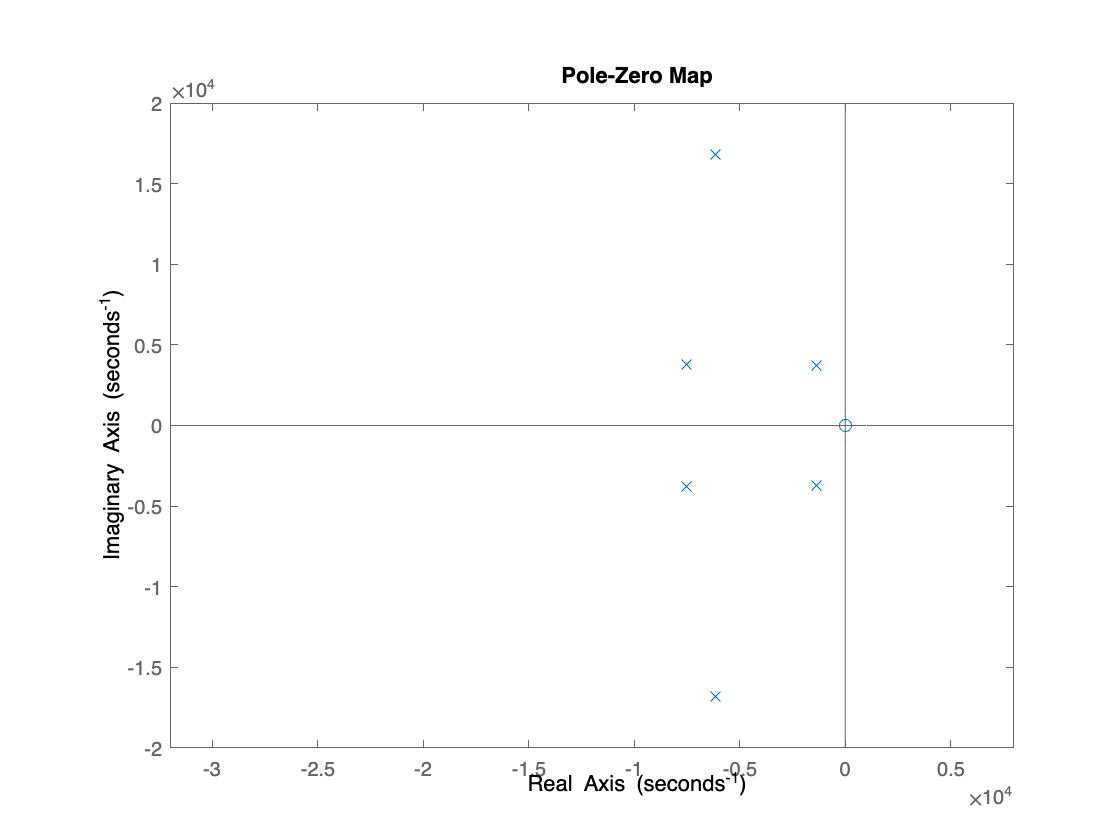


figure %Plot P-Z Map

pzplot(tf(bpnum6, bpden6))
axis([-32000 8000 -20000 20000])

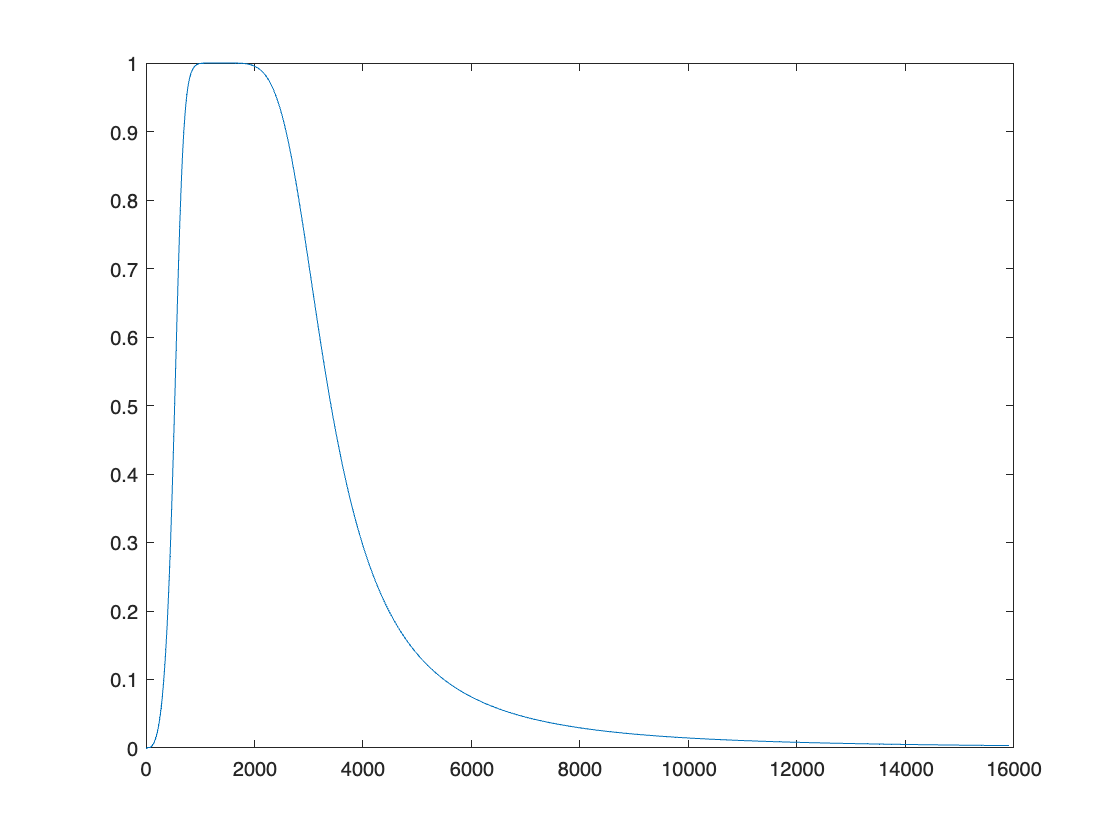

[Hbpa6, omega] = freqs(bpnum6, bpden6, num_pts_omega);

figure %Too much noise in BW, should cut off at 4kHz but is more like 16kHz

plot(omega/(2*pi), abs(Hbpa6))


% Approach 2 - 6th order LPF

[lpza6, lppa6, lpka6] = buttap(6) % Declare LPF zeroes, poles and gain


lpza6 =

     []



lppa6 =   -0.2588 + 0.9659i
  -0.2588 - 0.9659i
  -0.7071 + 0.7071i
  -0.7071 - 0.7071i
  -0.9659 + 0.2588i
  -0.9659 - 0.2588i


lpka6 = 1

%Declare numerators and denominators
[lpnum6, lpden6] = zp2tf(lpza6, lppa6, lpka6) 

lpnum6 =      0     0     0     0     0     0     1


lpden6 =     1.0000    3.8637    7.4641    9.1416    7.4641    3.8637    1.0000


%Declare denormalized num and denom
[lpnum6dn, lpden6dn] = lp2lp(lpnum6, lpden6, fha*2*pi) 

lpnum6dn = 4.4855e+25

lpden6dn = 1.0e+25 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0009    4.4855


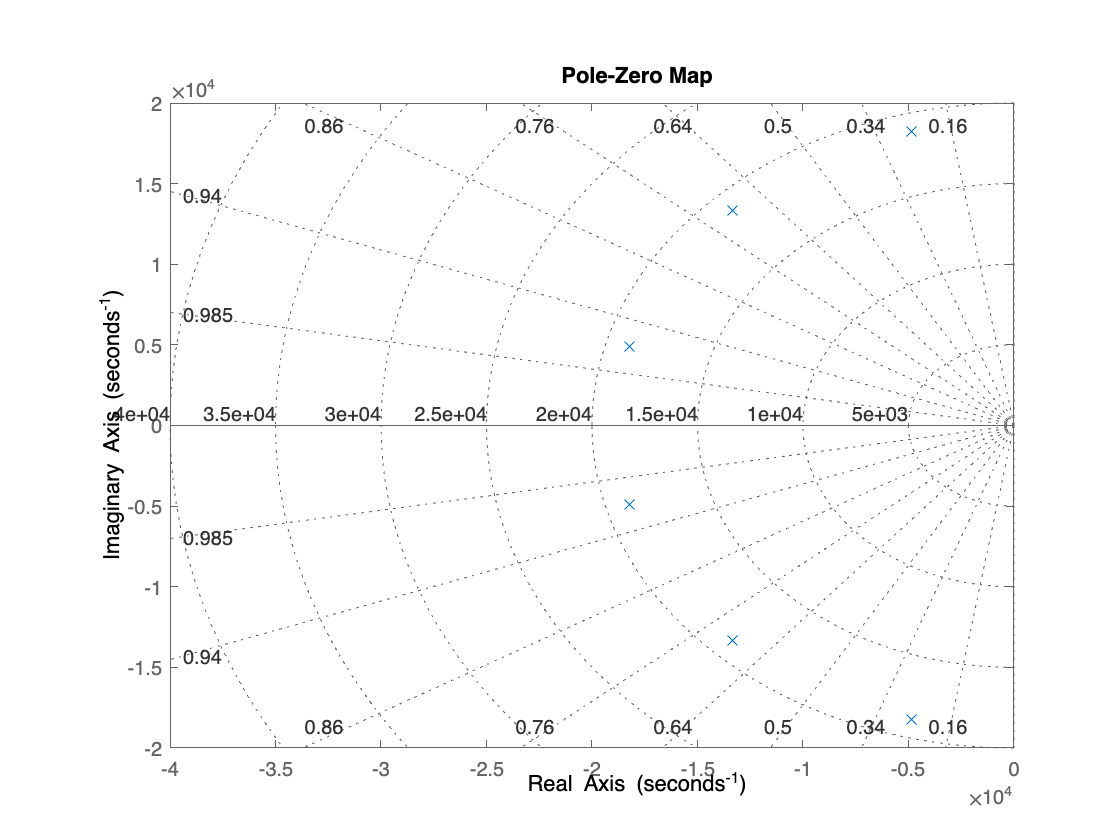


figure %Plot pole-zero Map
pzplot(tf(lpnum6dn, lpden6dn))
axis([-40e3 0 -20e3 20e3]); grid

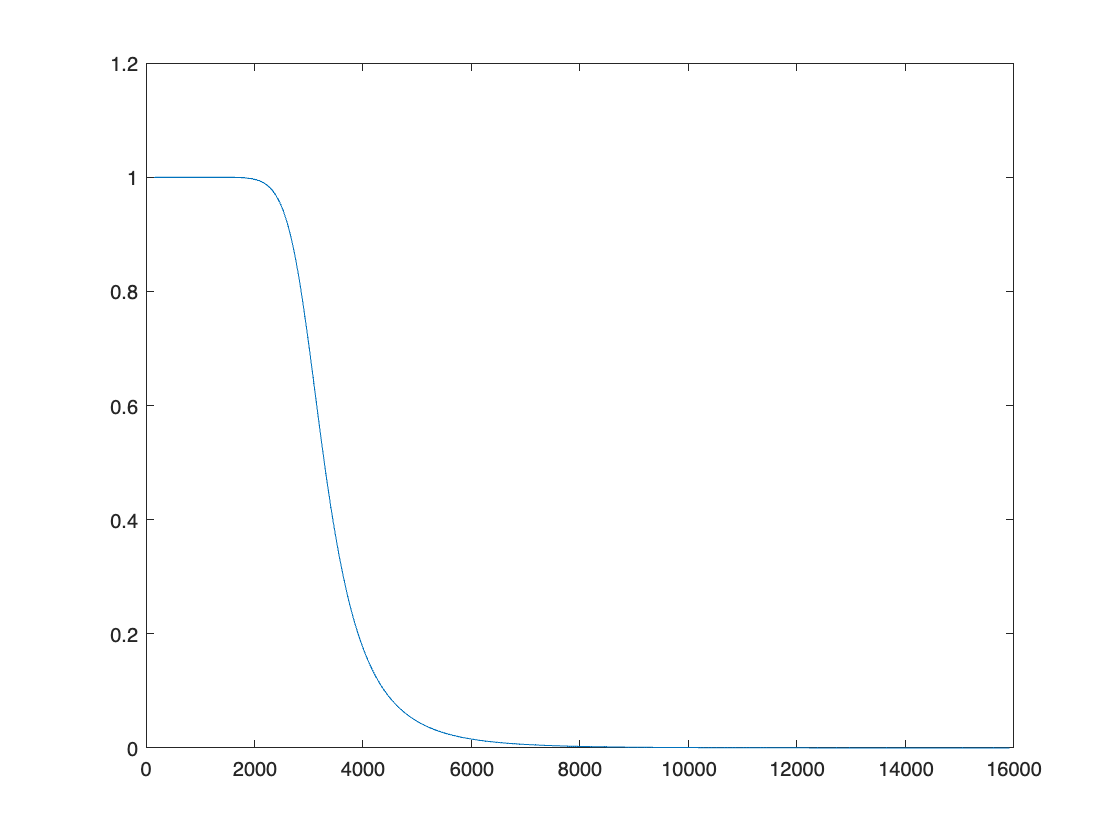

[hlp6dna, omega] = freqs(lpnum6dn, lpden6dn, num_pts_omega);

figure %Cutoff is now closer to 4kHz but still has some values above

plot(omega/(2*pi), abs(hlp6dna))

%Must prewarp signals so that when bilinear transformation 
%converts from analog to discrete, they will still be linear 
%and therefore readable


fs = 8000; % 2*fhigh
omega_l = (600/8000) * (2*pi) %Frequencies with new fs

omega_l = 0.4712

omega_h = 3000/8000 * (2*pi)

omega_h = 2.3562

omega_l_pw = 2*fs * tan(omega_l / 2) %Prewarped frequencies

omega_l_pw = 3.8413e+03

omega_h_pw = 2*fs * tan(omega_h / 2)

omega_h_pw = 3.8627e+04

omega_0_pw = sqrt(omega_l_pw * omega_h_pw)

omega_0_pw = 1.2181e+04

BW_pw = omega_h_pw - omega_l_pw

BW_pw = 3.4786e+04

%Converts 6th Order LPF to 6th Order BPF

bp_pw_num = 1.0e+13 *

    4.2094         0         0         0


bp_pw_den = 1.0e+24 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0015    3.2667


[bp_pw_num, bp_pw_den] = lp2bp(lpnum3, lpden3, omega_0_pw, BW_pw) 
%Bilinear transformation will be linear due to having better frequencies now
[numd, dend] = bilinear(bp_pw_num, bp_pw_den, fs) 

numd =     0.2569    0.0000   -0.7707   -0.0000    0.7707    0.0000   -0.2569


dend =     1.0000   -0.6448   -0.4166    0.0679    0.4287   -0.0673   -0.0563


[zd, pd, kd] = tf2zp(numd, dend) %Converts transfer function to zero-poles

zd =   -1.0000 + 0.0000i
  -1.0000 - 0.0000i
  -1.0000 + 0.0000i
   1.0000 + 0.0000i
   1.0000 - 0.0000i
   1.0000 + 0.0000i


pd =   -0.5267 + 0.5036i
  -0.5267 - 0.5036i
   0.7371 + 0.3550i
   0.7371 - 0.3550i
   0.5254 + 0.0000i
  -0.3014 + 0.0000i


kd = 0.2569

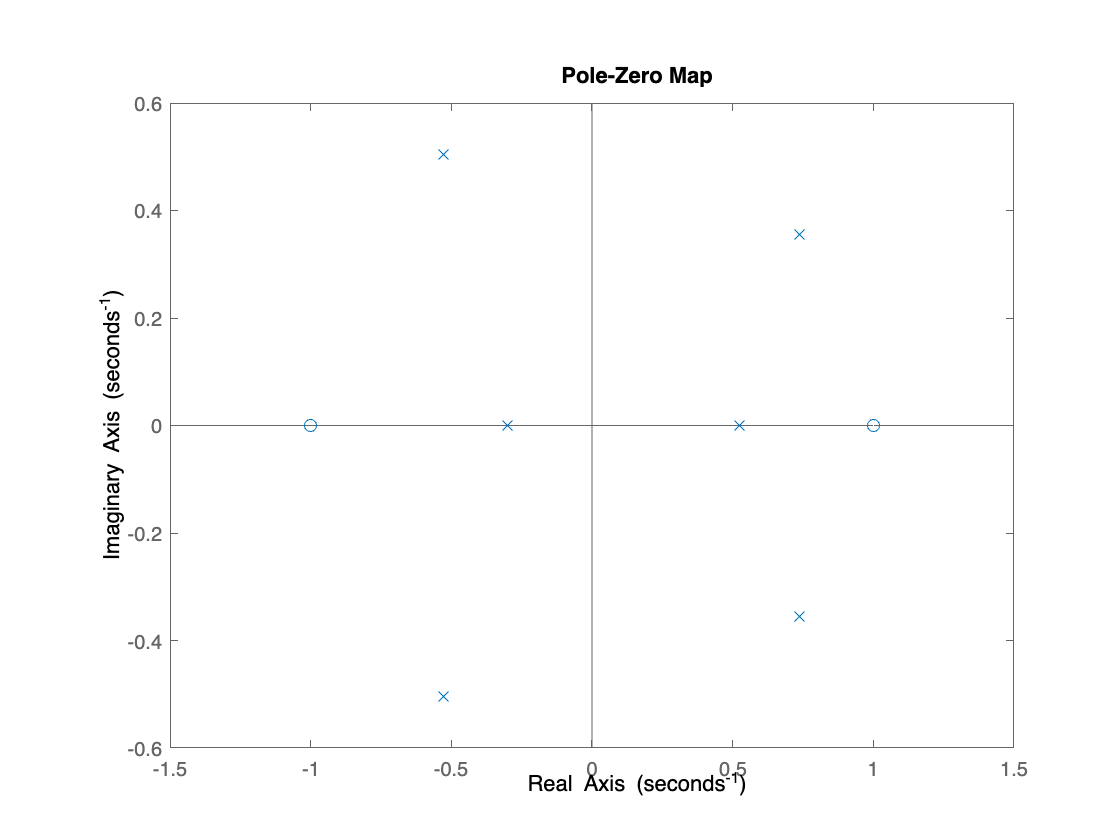

figure %Plot Pole-Zero map
pzplot(tf(numd, dend))

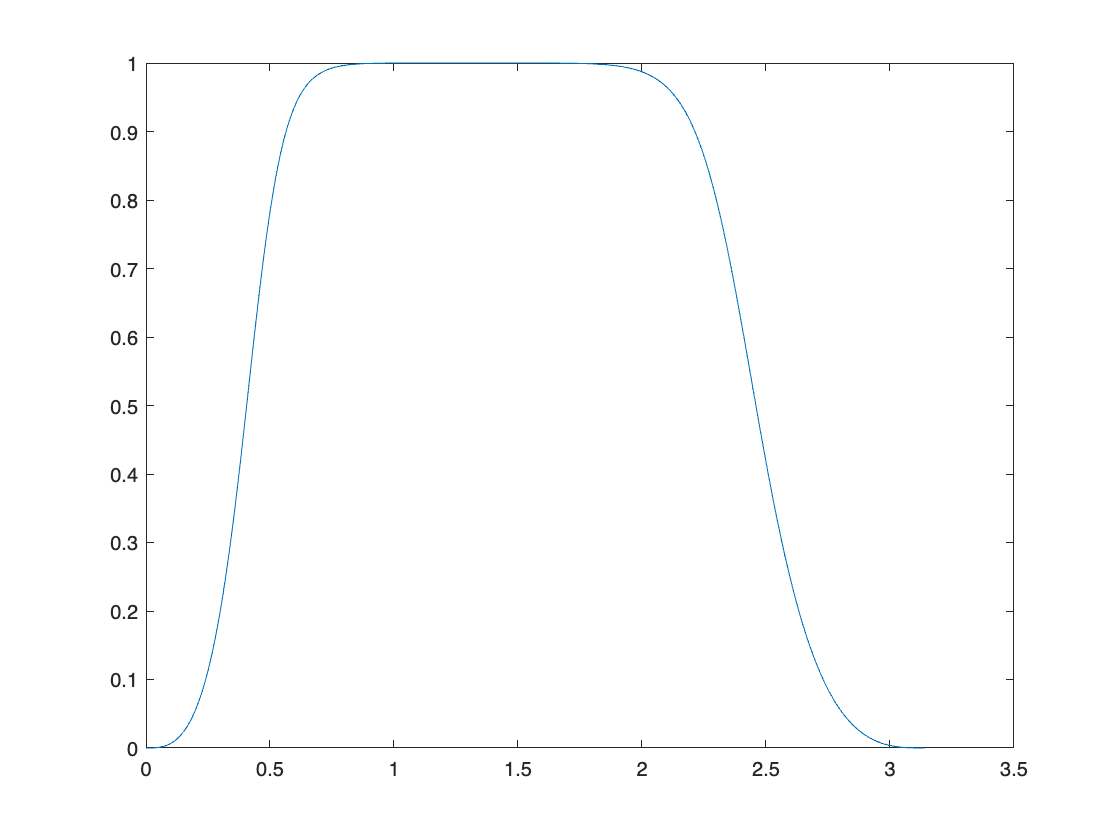

[Hd, omega2] = freqz(numd, dend, num_pts_omega);

%All amplitudes are now within the required frequency 
%ranges and there is no noise

plot(omega2, abs(Hd)) %Prewarped

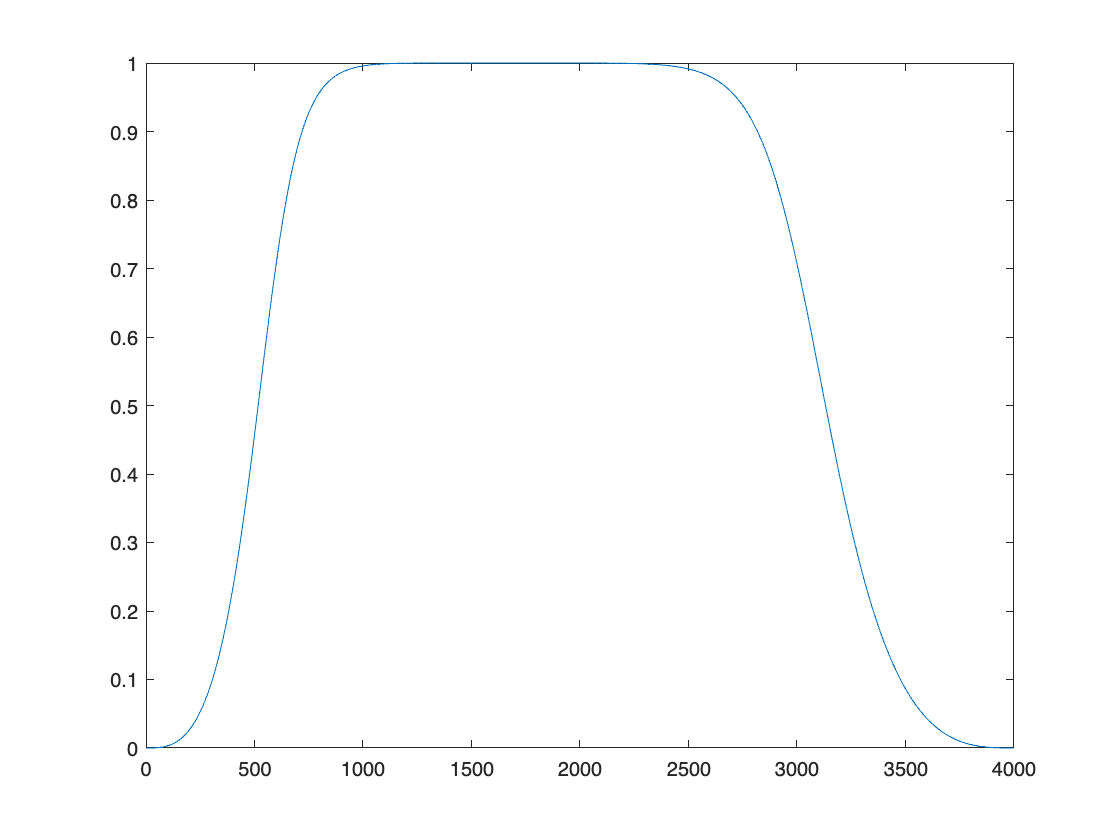

figure
plot(omega2/2/pi*8000, abs(Hd)) %Not prewarped

% Comment on the two approaches. 
% Describe which one you would choose and why. Be specific regarding reasons.  

%The second approach is much better than the first. In the first approach,
%there was a lot of noise beyond the maximum cutoff frequency and therefore
%did not make a good filter. The second filter reduces aliasing by
%implementing a 6th order analog lowpass filter, denormalizing, prewarping, 
%changing it to a band pass filter it then putting it through bilinear 
%transformation. 

%I would choose the second approach as this will have reduced aliasing and
%a lot less noise. This approach only contains values within the required
%frequencies (doesn't have values above 4kHz). Due to the bilinear
%transformations, prewarping and denormalizing, this approach results in a
%much more accurate final product.